% standard normal
f = @(x) 1/sqrt(2.*pi) * exp((-1/2)*x.^2)

f = function_handle with value:
    @(x)1/sqrt(2.*pi)*exp((-1/2)*x.^2)


x = linspace(-5, 5, 100);
rs = fast_rand_eca(1000, 1);

columns_to_sample =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


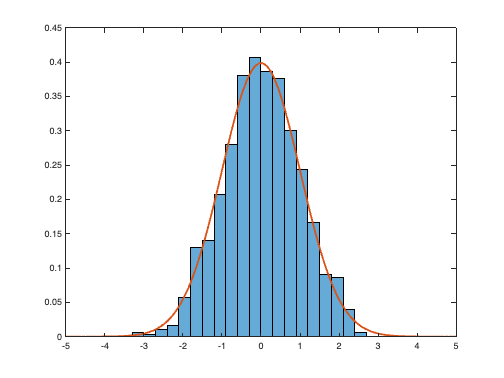


histogram(rand_to_pdf(rs, f, -5, 5, 1000), "Normalization", "pdf")
hold on
plot(x, f(x), "LineWidth", 2)
hold off

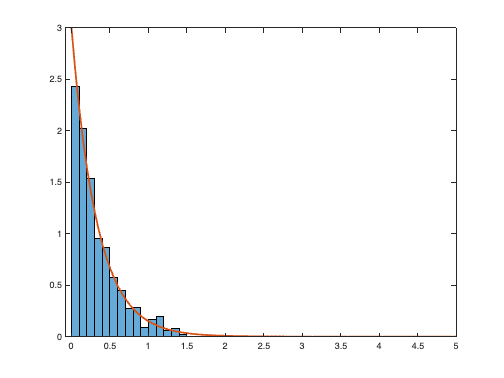



% exponential distribution
lambda = 3;
f =  @(x) lambda*exp(-x*lambda);
x = linspace(0, 5, 100);

histogram(rand_to_pdf(rs, f, 0, 5, 1000), "Normalization", "pdf")
hold on
plot(x, f(x), "LineWidth", 2)
hold off



% multiple normal distributions placed at different places
f = @(x) 1/sqrt(2.*pi) * exp((-1/2)*x.^2)

f = function_handle with value:
    @(x)1/sqrt(2.*pi)*exp((-1/2)*x.^2)


f = @(x) (1/3) * (f(x-3) + f(x) + f(x+4)) 

f = function_handle with value:
    @(x)(1/3)*(f(x-3)+f(x)+f(x+4))


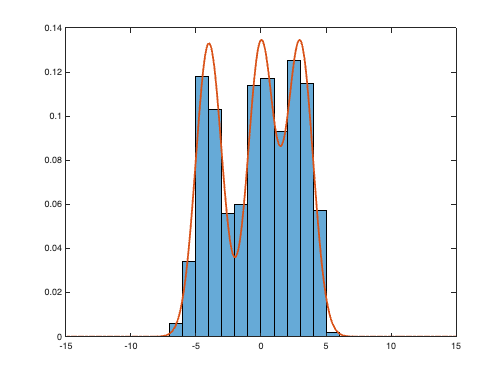

x = linspace(-15, 15, 500);

histogram(rand_to_pdf(rs, f, -15, 15, 1000), "Normalization", "pdf")
hold on
plot(x, f(x), "LineWidth", 2)
hold off

% rng(0)
% rng_eca()
N = 1000000;
histogram(fast_rand_eca(N, 1), "Normalization", "pdf");

columns_to_sample =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


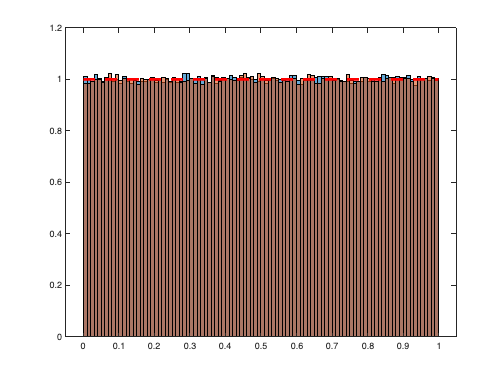

hold on
histogram(rand(N, 1), "Normalization", "pdf");
hold on
plot([0 1], [1 1], "r--", "LineWidth", 3)
hold off